clear; clc;
format long;
data = csvread('data.csv', 1, 0);

hold on;
scatter(data(:,1), data(:,2));
label0 = 'csv-data';
hold off;

% target fuction
fx_target = @(x) -0.28050164938036803*x^2 + 2.840081428868615*x + 2.1405420666290227;

% { {1}, {1}, {1} } prior matrix At times A was multiplied by 716.25
fx_all_one_in_b = @(x) 6.804669725344939E-6*x^2 - 9.705782574101767E-5*x + 3.1928008253981355E-4;
% { {1}, {1}, {1} } prior matrix At times A was divided by 716.25
fx_all_one_in_b1 = @(x) 3.490891259770014*x^2 - 49.79202948081704*x + 163.79517221908594;

% { {716.25}, {716.25}, {716.25} } prior matrix At times A was multiplied by 716.25
fx_all_716_in_b = @(x) 0.004873844690778314*x^2 - 0.06951766768700393*x + 0.22868435911914156;
% { {716.25}, {716.25}, {716.25} } prior matrix At times A was divided by 716.25
fx_all_716_in_b1 = @(x) 2500.3508648102757*x^2 - 35663.54111563524*x + 117318.29210192038;



% { {-716.25}, {-716.25}, {-716.25} } prior matrix At times A was multiplied by 716.25
fx_all_minus_716_in_b = @(x) -0.004873844690778314*x^2 + 0.06951766768700393*x - 0.22868435911914156;

% { {1}, {716.25}, {716.25^2} } prior matrix At times A was multiplied by 716.25
fx_polynom_in_b = @(x) 0.5037454468487075*x^2 - 5.032295927202879*x + 7.950243352519678;

% { {716.25^2}, {716.25}, {1} } prior matrix At times A was multiplied by 716.25
fx_polynom_rev_in_b = @(x) 8.081519020115088*x^2 - 99.41389149985218*x + 255.05803383580493;

% { {716.25^2}, {716.25^2}, {716.25^2} } prior matrix At times A was multiplied by 716.25
fx_polynom_pow_in_b = @(x) 3.490891259769969*x^2 - 49.79202948081658*x + 163.79517221908515;

% { {sqrt(716.25)}, {sqrt(716.25)}, {sqrt(716.25)} } prior matrix At times A was multiplied by 716.25
fx_polynom_sqrt_in_b = @(x) 1.8211233734531104E-4*x^2 - 0.0025975437775497072*x + 0.008544844121171779;

hold on;
plot1 = fplot(fx_target, [0, 10], 'LineWidth',2); 

label1 = 'target';
hold off;

hold on;
plot2 = fplot(fx_all_one_in_b, [0, 10], 'LineWidth',2); 

label2 = '[1, 1, 1] matrix A times At is MULTIPLIED with 716.25';
hold off;

hold on;
plot22 = fplot(fx_all_one_in_b1, [0, 10], 'LineWidth',2); 

label22 = '[1, 1, 1] matrix A times At is DIVIDED with 716.25';
hold off;

hold on;
plot3 = fplot(fx_all_716_in_b, [0, 10], 'LineWidth',2); 

label3 = '[716.25, 716.25, 716.25] matrix A times At is MULTIPLIED with 716.25';
hold off;

hold on;
plot31 = fplot(fx_all_minus_716_in_b, [0, 10], 'LineWidth',2); 

label31 = '[-716.25, -716.25, -716.25] matrix A times At is MULTIPLIED with 716.25';
hold off;

hold on;
plot4 = fplot(fx_polynom_in_b, [0, 10], 'LineWidth',2); 

label4 = '[1, 716.25, 716.25^2] matrix A times At is MULTIPLIED with 716.25';
hold off;

hold on;
plot5 = fplot(fx_polynom_rev_in_b, [0, 10], 'LineWidth',2); 

label5 = '[716.25^2, 716.25, 1] matrix A times At is MULTIPLIED with 716.25';
hold off;

hold on;
plot6 = fplot(fx_polynom_pow_in_b, [0, 10], 'LineWidth',2); 

label6 = '[716.25^2, 716.25^2, 716.25^2] matrix A times At is MULTIPLIED with 716.25';
hold off;

hold on;
plot7 = fplot(fx_polynom_sqrt_in_b, [0, 10], 'LineWidth',2); 

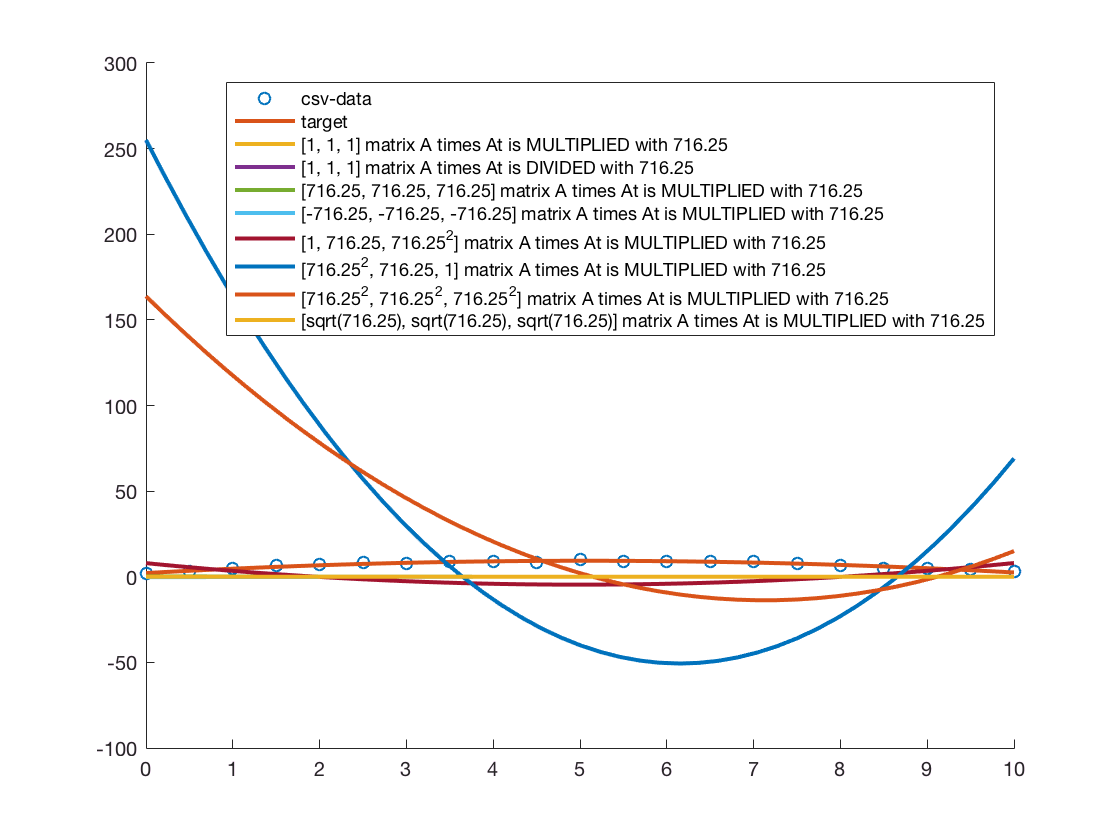

label7 = '[sqrt(716.25), sqrt(716.25), sqrt(716.25)] matrix A times At is MULTIPLIED with 716.25';
hold off;


legend(label0, label1, label2, label22, label3, label31, label4, label5, label6, label7)